clear all
addpath(genpath('~/tools/matlab'));
n = 120;
% Collected data
d=[];
d.cookies_morning = 30+7*randn(1,n);
d.ch_present      = binornd(zeros(1,n)+1, 0.5);
ch0 = find(d.ch_present == 0);
ch1 = find(d.ch_present == 1);
d.cookies_evening(ch0) = 2+2*randn(1, length(ch0));
d.cookies_evening(ch1) = 20+2*randn(1, length(ch1));
d.cookies_evening(find(d.cookies_evening<0)) = 0;
d.h               = 8;

## FIT


lb = [0 0 0]; % lower boundaries
ub = [10 1 1]; % upper boundaries
%X0 = [15 15]; % startin position
X0 = lb + rand(1,3).*ub

X0 =     5.2514    0.2260    0.0896



[X, err] = bads(@m2_error, X0, lb, ub, [], [], [], [], d);

Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -1.13257               1                              Uncertainty test
     0           5        -1.30703               1            Initial mesh      
     1           8        -1.33188             0.5             Refine grid      Train
     2          11        -1.36631             0.5    Incremental search (ES-ell)      
     2          12        -1.38998             0.5    Incremental search (ES-wcm)      
     2          17         -1.4077            0.25             Refine grid      Train
     3          21        -1.46694            0.25    Incremental search (ES-wcm)      
     3          25        -1.48711           0.125             Refine grid      
     4          29        -1.51099           0.125    Incremental search (ES-ell)      
     4          35        -1.51099          0.0625             Refine g

X

X =     7.6594    0.0984    0.2495


E2=[];P=[];
for r = 1:5
    % parameter limits

    lb = [0 0 0]; % lower boundaries
    ub = [10 1 1]; % upper boundaries
    %X0 = [15 15]; % startin position
    X0 = lb + rand(1,3).*ub
    
    [X, err] = bads(@m2_error, X0, lb, ub, [], [], [], [], d);
    P(r,:) = X;
    E2(r) = err;
end

X0 =     1.4205    0.0163    0.3330


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2       -0.655799               1                              Uncertainty test
     0           5        -1.38098               1            Initial mesh      
     1           8        -1.38246             0.5             Refine grid      Train
     2          10        -1.38988             0.5    Incremental search (ES-wcm)      
     2          15        -1.38988            0.25             Refine grid      
     3          18        -1.45514            0.25    Incremental search (ES-wcm)      
     3          19        -1.47225            0.25    Incremental search (ES-wcm)      
     3          24         -1.4799           0.125             Refine grid      
     4          33        -1.48635          0.0625             Refine grid      
     5          36        -1.49138          0.0625    Incremental search (ES-wcm)  

X0 =     3.4951    0.1587    0.9082


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -0.96318               1                              Uncertainty test
     0           5        -1.39113               1            Initial mesh      
     1           8        -1.39113             0.5             Refine grid      Train
     2          17        -1.40968            0.25             Refine grid      Train
     3          20        -1.42636            0.25    Incremental search (ES-wcm)      
     3          27        -1.44678           0.125             Refine grid      Train
     4          36        -1.45052          0.0625             Refine grid      Train
     5          38        -1.46019          0.0625    Incremental search (ES-wcm)      
     5          40         -1.4658          0.0625    Incremental search (ES-ell)      
     5          45        -1.46856         0.03125             Refin

X0 =     1.9383    0.3817    0.5426


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -0.77561               1                              Uncertainty test
     0           5        -1.24246               1            Initial mesh      
     1           8        -1.24676             0.5             Refine grid      Train
     2          10        -1.40815             0.5    Incremental search (ES-wcm)      
     2          16        -1.40815            0.25             Refine grid      Train
     3          17        -1.41139            0.25    Incremental search (ES-wcm)      
     3          24        -1.42097           0.125             Refine grid      
     4          33         -1.4212          0.0625             Refine grid      
     5          35        -1.42502          0.0625    Incremental search (ES-wcm)      
     5          37        -1.42969          0.0625    Incremental search (ES-w

X0 =     0.8010    0.1253    0.2839


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2       -0.975724               1                              Uncertainty test
     0           5        -1.27455               1            Initial mesh      
     1           8        -1.30692             0.5             Refine grid      Train
     2           9        -1.33964             0.5    Incremental search (ES-wcm)      
     2          17        -1.43077            0.25             Refine grid      Train
     3          20        -1.43785            0.25    Incremental search (ES-ell)      
     3          25        -1.43785           0.125             Refine grid      
     4          28         -1.4605           0.125    Incremental search (ES-ell)      
     4          33         -1.4605          0.0625             Refine grid      
     5          41         -1.4605         0.03125             Refine grid    

X0 =     0.0607    0.0443    0.3671


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2       -0.804699               1                              Uncertainty test
     0           5        -1.31375               1            Initial mesh      
     1           8        -1.39622             0.5             Refine grid      Train
     2          17        -1.39622            0.25             Refine grid      Train
     3          26        -1.39622           0.125             Refine grid      Train
     4          34        -1.47192            0.25         Successful poll      
     5          42        -1.47192           0.125             Refine grid      
     6          50        -1.47192          0.0625             Refine grid      Train
     7          60        -1.47192        0.015625             Refine grid      Train
     8          61        -1.47507        0.015625    Successful search (ES-ell)    

E2

E2 =    -1.5281   -1.4802   -1.4391   -1.4662   -1.4843


P

P =     7.6680    0.0987    0.2492
    7.8404    0.1406    0.0099
    8.3379    0.2952    0.9574
    9.9744    0.4553    0.9693
    6.9079    0.6433    0.9427


id = find(E2==min(E2))
p_best = P(id, :)

o = m2(p_best,d)

o = struct with fields:
    pred_cookies_evening: NaN
                    c_ev: [1×120 double]
                       s: [1×120 double]


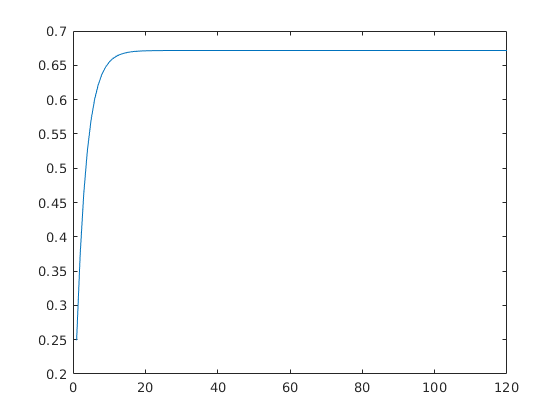

f=figure;
plot(1:numel(o.c_ev), o.s)

f=figure

f =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


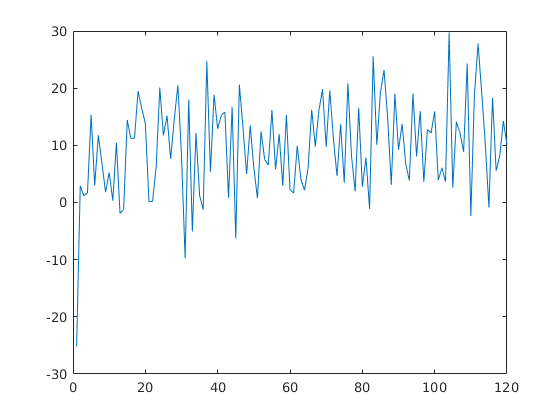

plot(1:numel(o.c_ev), o.c_ev)